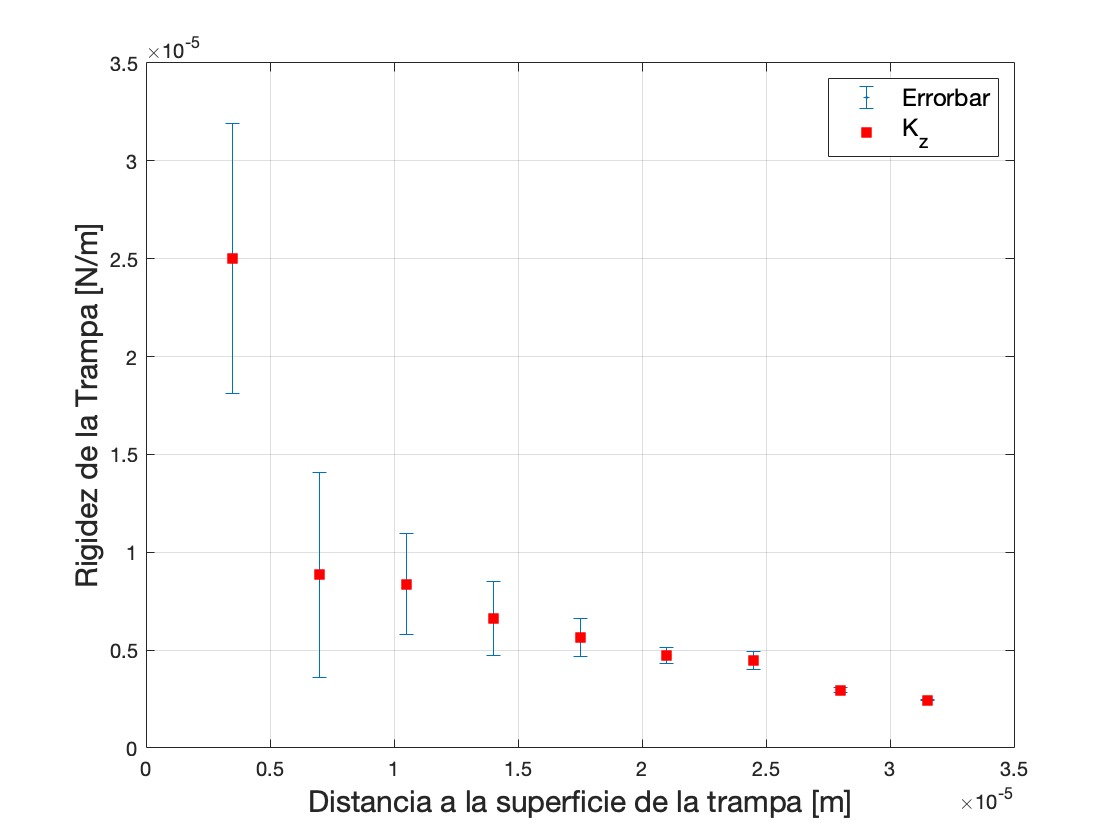

DatosK = readmatrix("k_z.txt");
d = DatosK(:,1);
k = DatosK(:,2);

c1 = 2.331e-5;
c2 = 7.208e4;
fk = c1 *exp(-c2*d);
er = abs(fk - k);

%%errorbar(d,fk,er,"o");
%%hold on
%%plot(d,k,"r.");
%%legend('Errorbar','K');

%%errorbar(d,fk,er,'-s','MarkerSize',1,...
    %%'MarkerEdgeColor','red','MarkerFaceColor','red')
    
errorbar(d,k,er,"*",'MarkerSize',1);
hold on 
plot(d,k,"s",'MarkerSize',6,'MarkerEdgeColor' ...
    ,'red','MarkerFaceColor','red');
legend('Errorbar','K_z','FontSize',12);
xlabel('Distancia a la superficie de la trampa [m]','FontSize',15);
ylabel('Rigidez de la Trampa [N/m]','FontSize',15);
grid on 